# Hausaufgabe | Projektpraktikum Matlab

## Programmiertechnik II: Performance Audio

## Gruppenmitglieder

- Mitglied 1:  Johannes Truong Le (03637523)

- Mitglied 2:  Bernhard Birkner (03637368)

- Mitglied 3:  Sebastian Getz (03623589)

## Allgemeine Hinweise

- Hausaufgaben werden in Gruppen von max. 3 Personen bearbeitet

- Eine gemeinsame Lösung pro Gruppe wird eingereicht

- Jede Datei muss die Namen aller Mitglieder im Header enthalten

- Ihre Lösung der Aufgabe ergänzen Sie in der Datei mit der Aufgabenstellung direkt unterhalb der einzelnen Teilaufgaben. Wird explizit eine Funktion gefordert, liefern Sie diese als *.m-Datei ab

- Textuelle Antworten werden als Text im Live-Editor formatiert

- Code wird im Code-Modus im Live-Editor hinzugefügt

- Abgabe der Lösung erfolgt unter [www.moodle.tum.de](http://www.moodle.tum.de)

## Aufgabenstellung

In der digitalen Signalverarbeitung muss in vielen Fällen das Signal vor der Verarbeitung "gefenstert" werden. Darunter versteht man die Aufteilung eines langen Signals in mehrere, gleich lange Stücke (Frames), die jeweils mit einer Fensterfunktion multipliziert werden. Informationen dazu unter: `http://de.wikipedia.org/wiki/Fensterfunktion`

Das folgende Beispiel zeigt die Anwendung eines Hanning-Fensters auf ein zufälliges Signal:

## Beispiel

Länge eines Frames

frameSize = 128;

Fensterfunktion

win = hann(frameSize);

Beispiel zur Fensterung

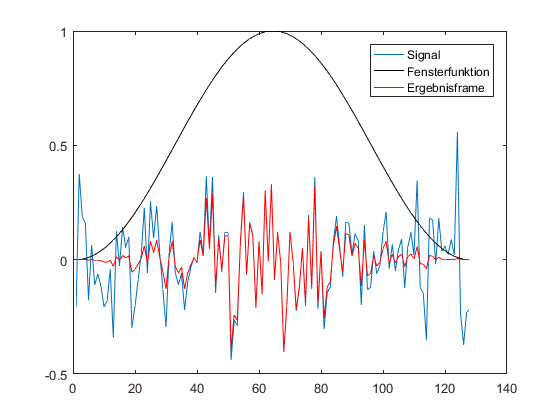

signal = 0.2*randn(frameSize,1);
figure, plot(signal);
hold on;
plot(win, 'k');
plot(signal.*win, 'r');
legend('Signal', 'Fensterfunktion', 'Ergebnisframe');
hold off;

## Anwendung

Im Folgenden wird das Fenster auf eine längere Audio-Sequenz angewendet. Das Ergebnis der Fensterung ist eine Matrix, die mehrere Frames beinhaltet. Dabei stellt die erste Spalte der Matrix die ersten 128 Samples des Audiosignals gewichtet mit der Fensterfunktion dar. Die zweite Spalte beinhaltet die nächsten 128 gewichtetet Samples usw. Ziel der Aufgabe ist es, den Code, der sich innerhalb der Zeitmessung befindet, zu beschleunigen. Um halbwegs verlässliche Werte fuer den Beschleunigungsfaktor zu erhalten, müssen Sie das Skript mehrmals ausführen.

Signal einlesen

load('handel.mat');

Verlängere Signal auf ein ganzahliges Vielfaches der Framelänge

y = [y; zeros(ceil(size(y,1)/frameSize)*frameSize - size(y,1),1)];

Zähle Anzahl der Frames

sigLen = size(y,1);
numFrames = sigLen / frameSize;

Initialisiere Ergebnismatrizen

res = zeros(frameSize, numFrames);
res2 = zeros(frameSize, numFrames);
frame = zeros(frameSize,1);

Start der Zeitmessung

tic;
cnt = 1;
for k = 1:frameSize:sigLen
    % Kopiere erstes Signalstueck aus dem Signal
    sigPart = y(k:k+frameSize-1);
    
    % Multipliziere Signalstueck mit dem Fenster
    for l = 1:frameSize
        frame(l,1) = sigPart(l,1) * win(l,1);
    end
    
    % Kopiere Frame in die Ergebnismatrix
    res(:,cnt) = frame;
    cnt = cnt + 1;
end

% Ende der Zeitmessung
disp('Laufzeit'); laufzeitOrg = toc

Laufzeit


laufzeitOrg = 10.3929

## Aufgabe

Fügen Sie hier Ihren Code zur Berechnung von `res2` ein. `res2` soll das gleiche Ergebnis wie `res` enthalten.

tic;

% res2 ist bereits vorinitalisiert, also schon "optimal"

% splitte das Signal in die einzelnen Frames
y_split = reshape(y,frameSize,numFrames);

% erweitere das Fenster
win2 = repmat(win,1,numFrames);

% berechne res2
res2 = y_split .* win2;


laufzeitNeu = toc

laufzeitNeu = 0.0202

Beschleunigungsfaktor = laufzeitOrg/laufzeitNeu

Beschleunigungsfaktor = 513.8659